## PARAMETERS

clearvars
close all

dop = 10E3; % doppler frequency
phi = 0;

sigma = 0.1;    % noise variance 

inout = InOutInterface();

% directories
indir = "inData";
inout.configCreateSettings(indir);
outdir = "outData";
inout.configSaveResults(outdir);

filename = "in0.json";
PRNfilename = "PRNpattern.json";
settings = inout.createSettings(filename,PRNfilename);

down = DownconverterFilter();
down.configDownConverter(settings.fSampling);

## PRN SEQUENCE GENERATION

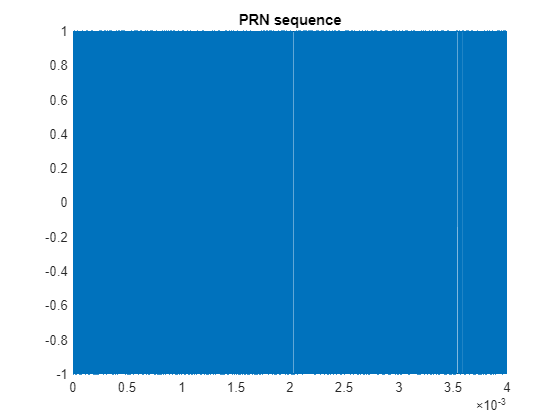

% if length(inout.PRNcode)~=4092 disp("Error in PRN sequence length"); end
% if inout.PRNcode == 1
%     code1="F5D710130573541B9DBD4FD9E9B20A0D59D144C54BC7935539D2E75810FB51E494093A0A19DD79C70C5A98E5657AA578097777E86BCC4651CC72F2F974DC766E07AEA3D0B557EF42FF57E6A58E805358CE9257669133B18F80FDBDFB38C5524C7FB1DE079842482990DF58F72321D9201F8979EAB159B2679C9E95AA6D53456C0DF75C2B4316D1E2309216882854253A1FA60CA2C94ECE013E2A8C943341E7D9E5A8464B3AD407E0AE465C3E3DD1BE60A8C3D50F831536401E776BE02A6042FC4A27AF653F0CFC4D4D013F115310788D68CAEAD3ECCCC5330587EB3C22A1459FC8E6FCCE9CDE849A5205E70C6D66D125814D698DD0EEBFEAE52CC65C5C84EEDF207379000E169D318426516AC5D1C31F2E18A65E07AE6E33FDD724B13098B3A444688389EFBBB5EEAB588742BB083B679D42FB26FF77919EAB21DE0389D9997498F967AE05AF0F4C7E177416E18C4D5E6987ED3590690AD127D872F14A8F4903A12329732A9768F82F295BEE391879293E3A97D51435A7F03ED7FBE275F102A83202DC3DE94AF4C712E9D006D182693E9632933E6EB773880CF147B922E74539E4582F79E39723B4C80E42EDCE4C08A8D02221BAE6D17734817D5B531C0D3C1AE723911F3FFF6AAC02E97FEA69E376AF4761E6451CA61FDB2F9187642EFCD63A09AAB680770C1593EEDD4FF4293BFFD6DD2C3367E85B14A654C834B6699421A";
%     if sum(bitxor(inout.PRNcode,hexToBinaryVector(code1)))>0 disp("Error in PRN sequence reading"); end
% end

tchip = (0:length(inout.PRNcode)-1)' / settings.chipRate;
upsampling = settings.fSampling / settings.chipRate;
t = (0:upsampling*length(inout.PRNcode)-1)' / settings.fSampling;
k=2*interp1(tchip,single(inout.PRNcode),t,"previous")-1;

figure;
plot(t,k);
title("PRN sequence");

## BASEBAND SIGNAL GENERATION WITH NOISE

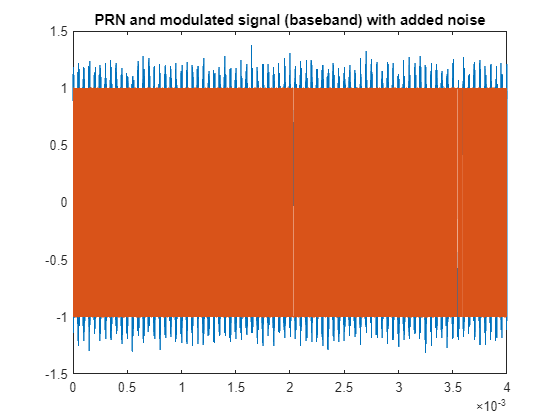

noise = sigma*randn(1,length(t))';
basebandsignaldopp = (k+noise).*exp(1i*2*pi*dop*t);

I = real(basebandsignaldopp);
Q = imag(basebandsignaldopp);

figure;
plot(t,I);
hold on;
plot(t,k);
title("PRN and modulated signal (baseband) with added noise");

## FILTERING THE BASEBAND SIGNAL

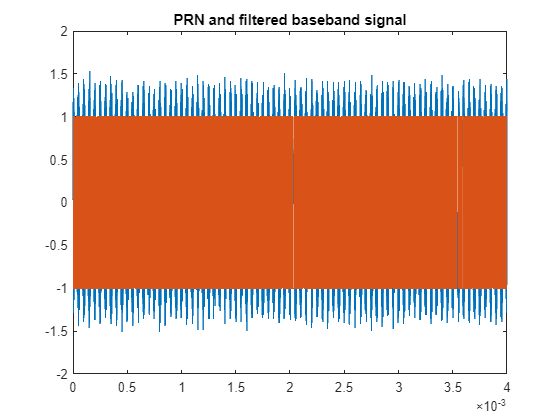

down.configFilter(2,1,50);

IQdownfilt = down.downFilter([I Q],2*settings.chipRate);

figure;
plot(t,IQdownfilt(:,1));
hold on;
plot(t,k);
title("PRN and filtered baseband signal");

## DOWNCONVERSION AND FILTERING

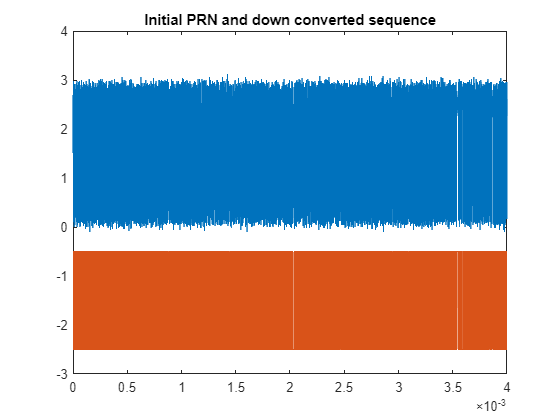

IQfinal = down.downConverter(IQdownfilt,dop,0);

down.configFilter(2,1,50);
IQdownfiltdop = down.downFilter(IQfinal,2*settings.chipRate);

figure;
plot(t,IQdownfiltdop(:,1)+1.5);
hold on;
plot(t,k-1.5);
title("Initial PRN and down converted sequence");

% fid=fopen("inData\test1_1.bin","w");
% fwrite(fid,reshape(repmat(mods,2,1),1,[]),"int32");
% fclose(fid);